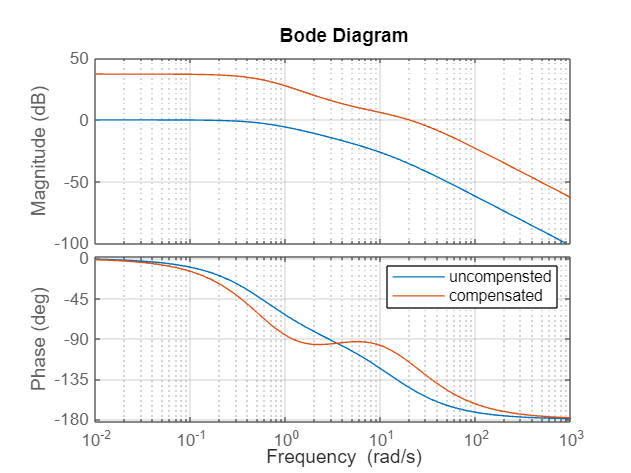

%NAME: WYCLIFFE MACHUKI OKENYE
%REG: EG209/106813/21
%CONTROL ASSIGNMENT

% Case 1: G1(s) = 9/(s^2 + 4 s + 9)
s = tf('s');
G1 = 8/(s^2 + 14*s + 8);%%open loopTf for uncompensated sytem

% Proposed compensators
C_lead = 80*(s+2)/(s+25);%%lead comaparator
C_lag  = (s+6)/(s+0.6);
C_T= C_lead * C_lag;%%lead and lag in cascade

% Closed-loop (unity feedback)
T1= feedback(C_T * G1, 1);


% bode plot for uncompenated system and compensated system
figure;
bode(G1, C_T*G1); 
legend('uncompensted','compensated');
grid on;

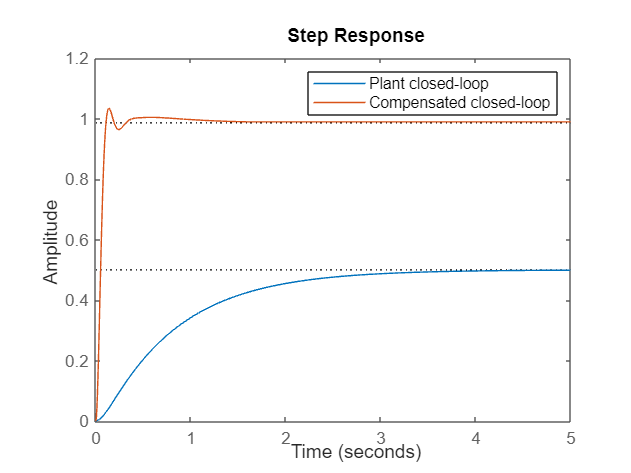

Step info for compensated case 1:


         RiseTime: 0.0701
    TransientTime: 0.2610
     SettlingTime: 0.2610
      SettlingMin: 0.9136
      SettlingMax: 1.0343
        Overshoot: 4.8680
       Undershoot: 0
             Peak: 1.0343
         PeakTime: 0.1383



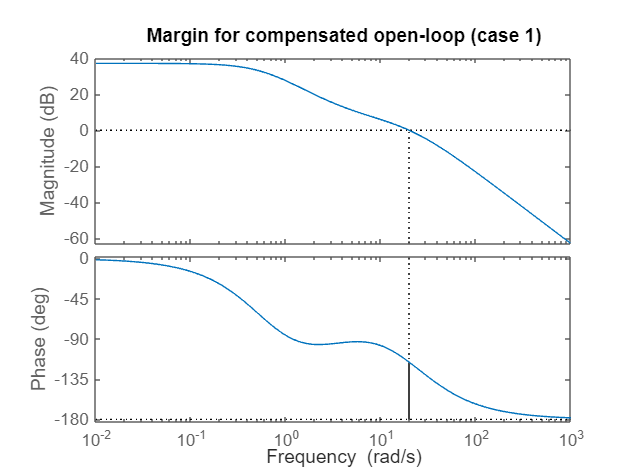

%%step polots for uncompensatedand fully_compensted system
figure; 
step(G1/(1+G1), T1); 
legend('Plant closed-loop','Compensated closed-loop');